By Ethan Harvey

This program runs KMeans on the dataset loaded in by the user. Below the number of footsteps in the dataset is declared.

NumTrainCase = 99;

 Below the label is added to each item in the dataset (left or right).

for ind_trnCase = 1:NumTrainCase
    if mod(ind_trnCase,2)==1
        Data(ind_trnCase,:)=stepOut(:,ind_trnCase);
        DatLabl(ind_trnCase)=categorical(cellstr('left'));
    else
        Data(ind_trnCase,:)=stepOut(:,ind_trnCase);
        DatLabl(ind_trnCase)=categorical(cellstr('right'));
    end
end
DatLabl = DatLabl';
DataTable=table(Data);
DatMean = DataTable

DatMean = 99×1 table
         Data     
    ______________

    [1×480 double]
    [1×480 double]
    [1×480 double]
    [1×480 double]
    [1×480 double]
    [1×480 double]
    [1×480 double]
    [1×480 double]
    [1×480 double]
    [1×480 double]
    [1×480 double]
    [1×480 double]
    [1×480 double]
    [1×480 double]
    [1×480 double]
    [1×480 double]


kMean = zeros(NumTrainCase,1);
DatMean.kMean=kMean;

Next the label is appended to the DatMean table.

DatMean.description=DatLabl;
first_step = DatMean.Data(1,:);
second_step = DatMean.Data(2,:);
third_step = DatMean.Data(3,:);
fourth_step = DatMean.Data(4,:);

Next a series average and edit is calculated. There is one series edit value for each footstep. The series edit is made up of integers ranging from -10 to 10 and is based off the distance of each footstep from the series average.

series_average = Average(NumTrainCase, DatMean);
series_edit = EditDistance(NumTrainCase, DatMean, series_average);

Then a number of generations are run using a KMean model.

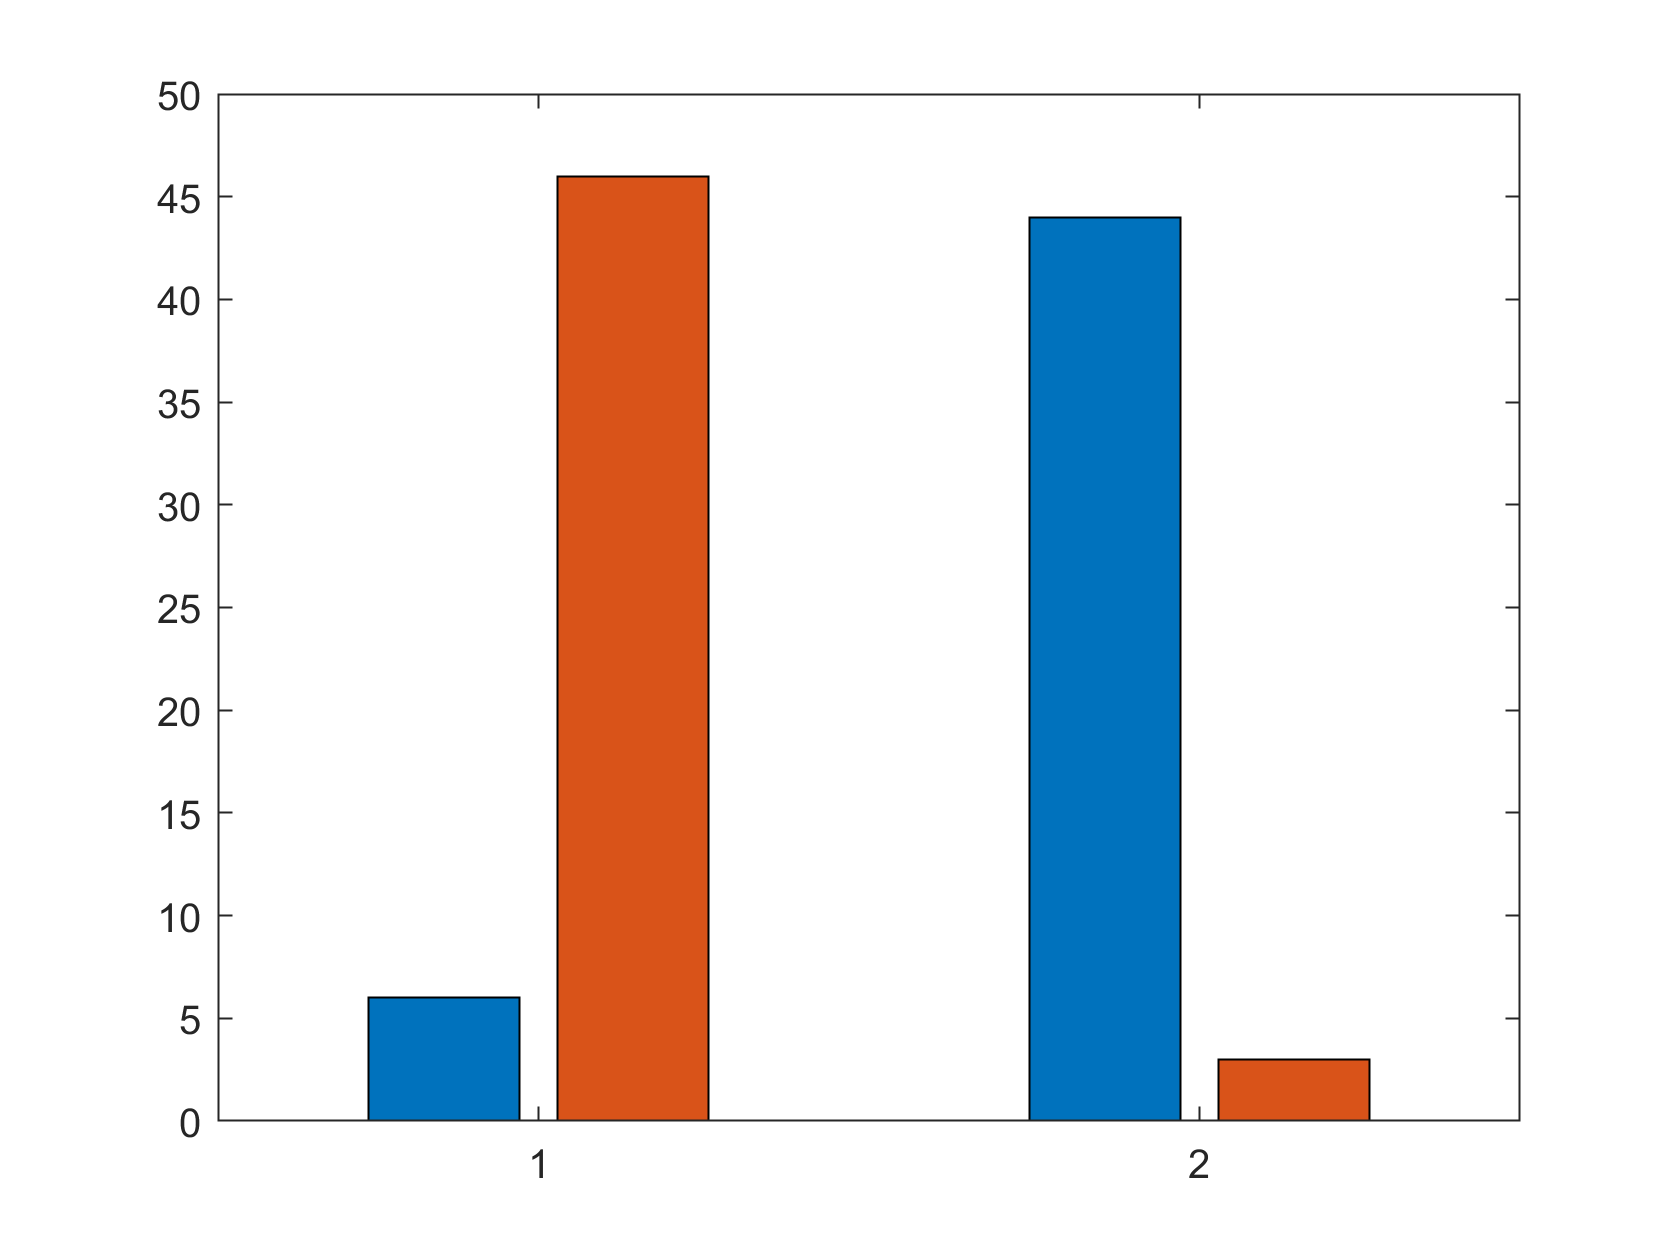

[DatMean, k1, k2] = KMeanFunction(NumTrainCase, DatMean, series_edit, second_step, third_step);
for i=1:10
    [DatMean, k1, k2] = KMeanFunction(NumTrainCase, DatMean, series_edit, k1, k2);
    left_ones = sum(DatMean.kMean==1 & DatMean.description=="left");
    right_ones = sum(DatMean.kMean==1 & DatMean.description=="right");
    left_twos = sum(DatMean.kMean==2 & DatMean.description=="left");
    right_twos = sum(DatMean.kMean==2 & DatMean.description=="right");
    bar([left_ones,right_ones;left_twos,right_twos]);
    x = input("Press enter for another iteration: ");
end

The resulting averages are plotted.

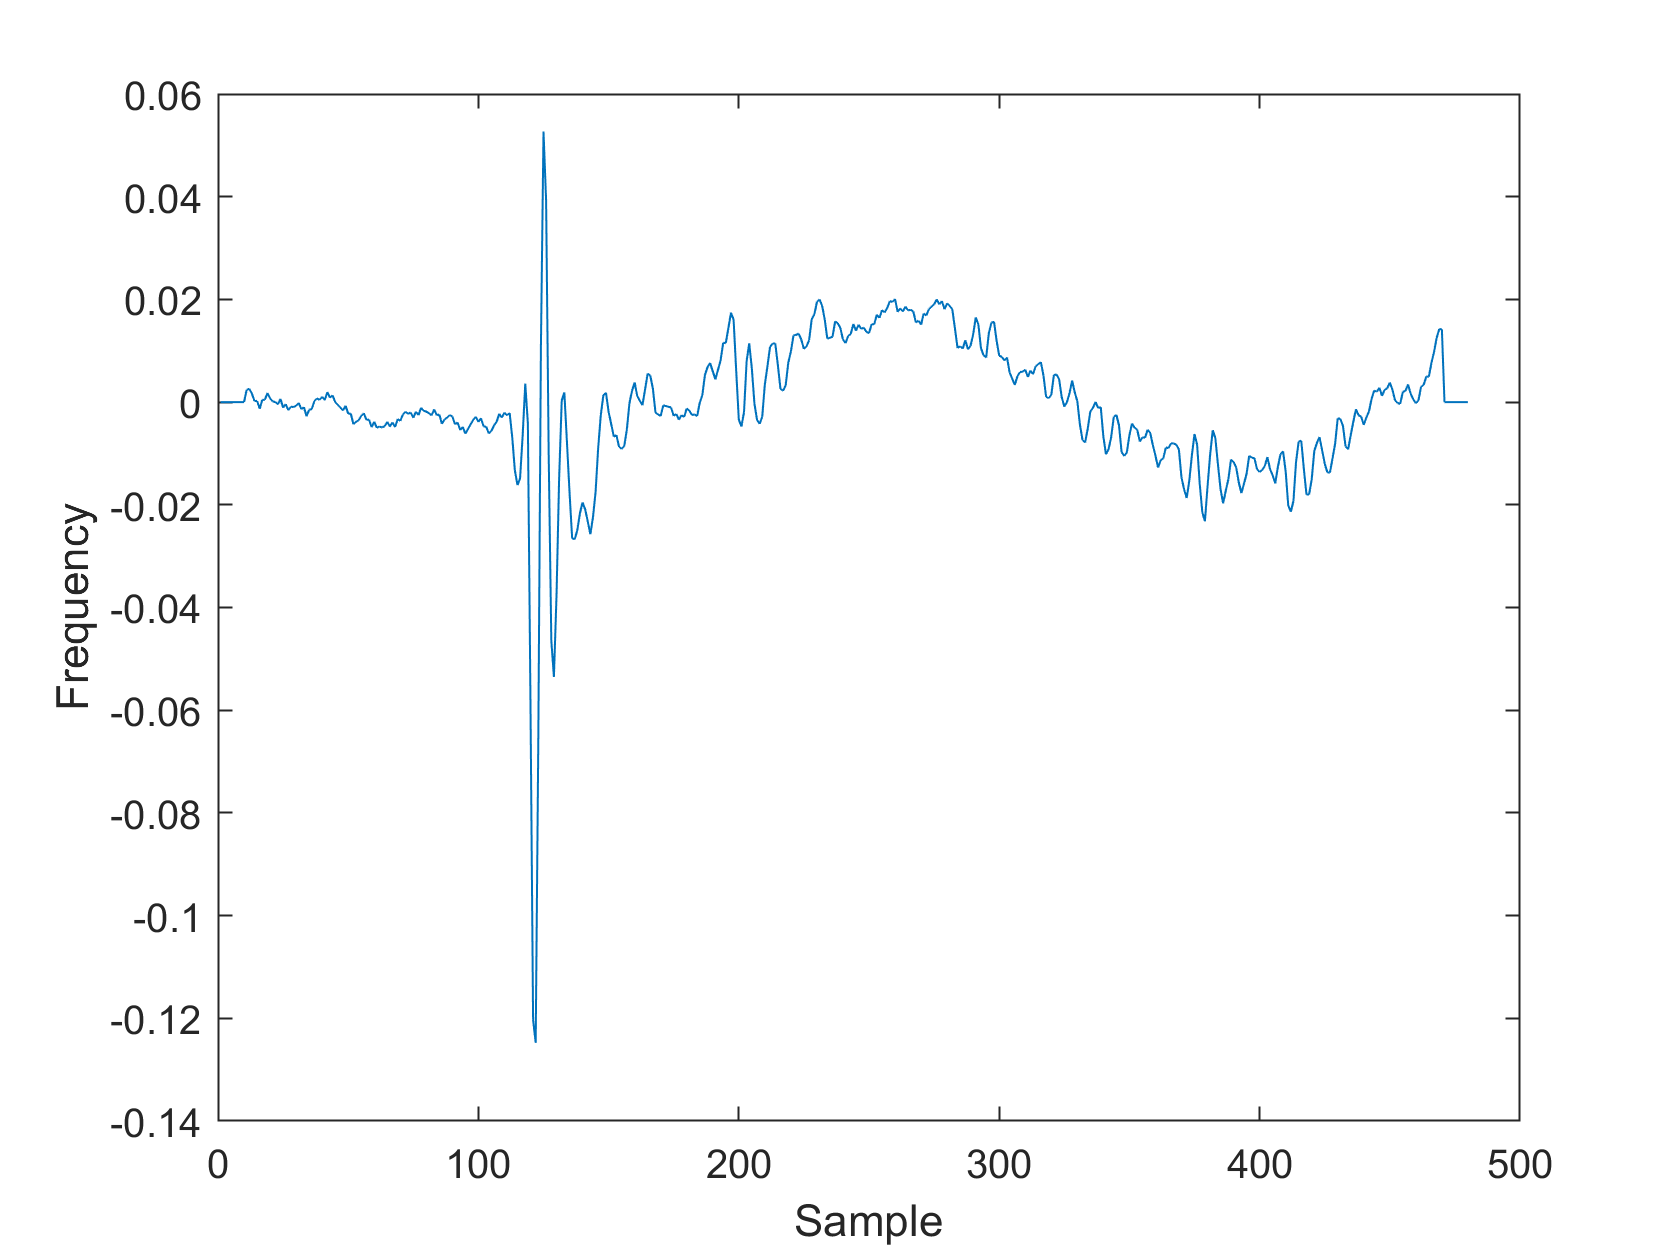

plot(k1);
ylabel('Frequency');
xlabel('Sample');

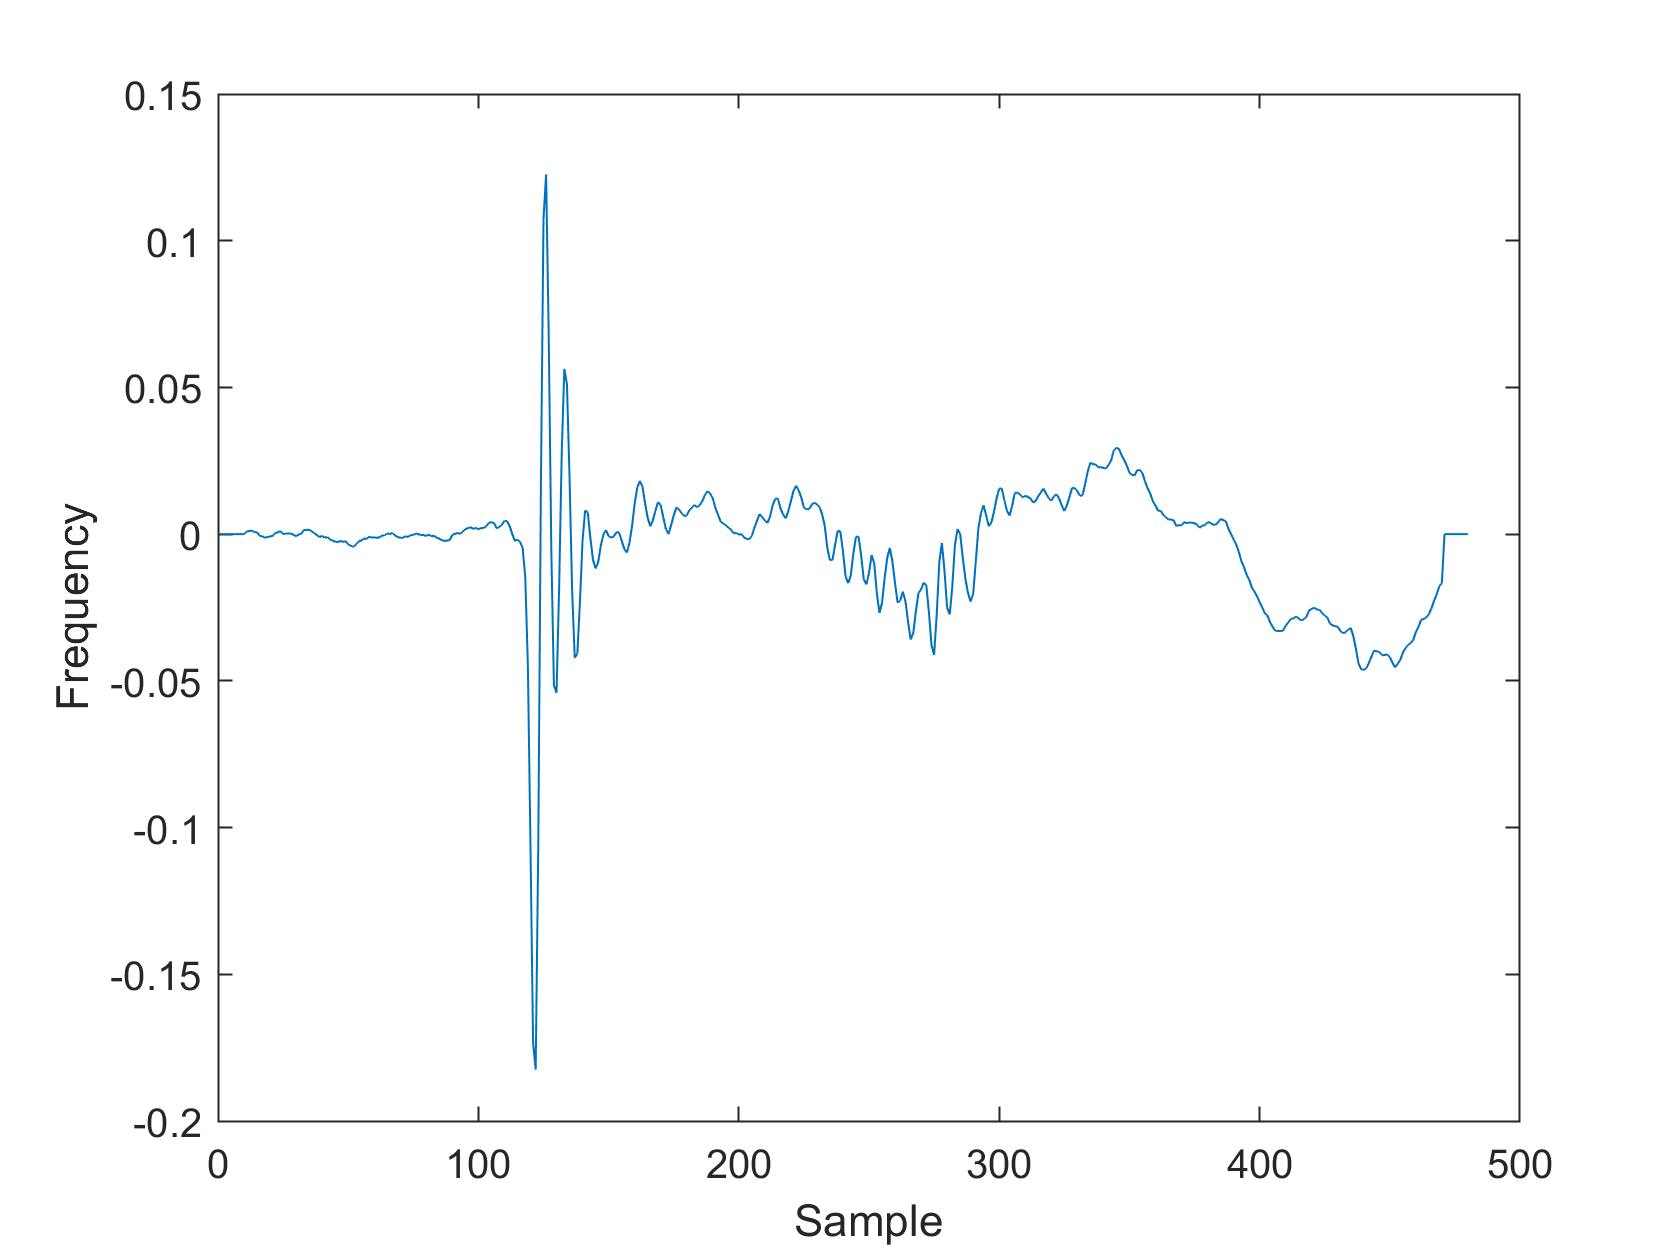

plot(k2);
ylabel('Frequency');
xlabel('Sample');

KMean function

function [DatMean, new_k1, new_k2] = KMeanFunction(NumTrainCase, DatMean, series_edit, k1, k2)
    new_k1 = zeros(1,480);
    new_k2 = zeros(1,480);
    k1_count = 0;
    k2_count = 0;

    for i=1:NumTrainCase
        k1_distance = 0;
        k2_distance = 0;
        for j=11:470
            k1_distance = k1_distance + abs(k1(1,j) - DatMean.Data(i,j+series_edit(i)));
            k2_distance = k2_distance + abs(k2(1,j) - DatMean.Data(i,j+series_edit(i)));
        end
        if (k1_distance < k2_distance)
            k1_count = k1_count + 1;
            for k=11:470
                new_k1(1,k) = new_k1(1,k) + DatMean.Data(i,k+series_edit(i));
            end
            DatMean.kMean(i) = 1;
        elseif (k2_distance < k1_distance)
            k2_count = k2_count + 1;
            for k=11:470
                new_k2(1,k) = new_k2(1,k) + DatMean.Data(i,k+series_edit(i));
            end
            DatMean.kMean(i) = 2;
        end
    end
    new_k1 = new_k1/k1_count;
    new_k2 = new_k2/k2_count;
end

Edit distance function

function [series_edit] = EditDistance(NumTrainCase, DatMean, series_average)
    series_edit = zeros(1,NumTrainCase);
    for i=1:NumTrainCase
        min_series_distance = 1000;
        for j=-10:10
            series_distance = 0;
            for k=11:470
                series_distance = series_distance + abs(series_average(1,k) - DatMean.Data(i,k+j));
            end
            if (series_distance < min_series_distance)
                min_series_distance = series_distance;
                series_edit(i) = j;
            end
        end
    end
end

 Average function

function [series_average] = Average(NumTrainCase, DatMean)
    series_average = zeros(1,480);
    for i=1:NumTrainCase
        for j=1:480
            series_average(j) = series_average(j) + DatMean.Data(i,j);
        end
    end
    series_average = series_average/NumTrainCase;
end
